# Treasure Hunt Game

Welcome to the MATLAB Treasure Hunt Module, designed to teach you how to make a fun treasure hunting game while learning some core Computer Science concepts along the way. We recommend that you complete our other module, Fundamentals of Programming, to help you better understand the ideas brought up in this module. We hope you enjoy it!

When it is finished, the game will look like this:

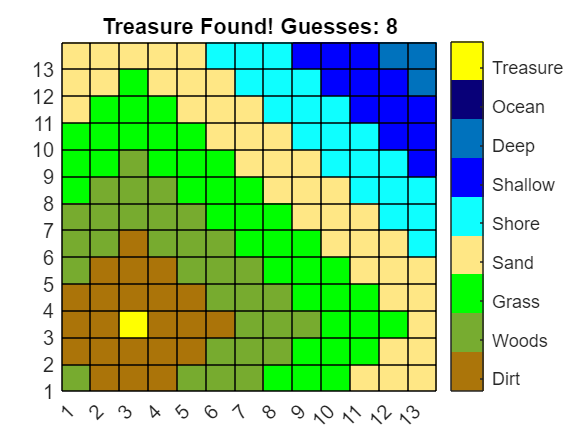

Learn fundamental computer science concepts by making a fun treasure hunting game.

   At various points throughout this live script, you will be asked to check that your output matches the expected output. To do this, we recommend to remove the semicolons in your code and check the inline output for accuracy. Don't forget to put the semicolons back when you're done so that you can avoid unnecessary output!

## Section 1: Creating Variables

Variables are a great way to store information to use later. Some of the information for this game we want to save includes the size of the treasure map, the treasure location, and the number of guesses the player has made.

### Your first variable

First, let's start by making a variable to represent the number of guesses the player has made. We want this variable to be equal to 0 because the player will have made zero guesses at the start of the game. 

  **Try**. Create a variable called *guessNum* that is equal to 0. You should see output stating "guessNum = 0".

  **Pro-tip**. A great way to name your variables is to use camel case. This means that the first word in your variable name is lowercase, while the rest of the words all begin with an uppercase letter. For example, if you wanted to name your variable "the coolest variable ever" using camel case, it would look like this: *theCoolestVariableEver*

% Write your code here
guessNum = 0;

### Let's make two more

Next, we want to choose the size of the treasure map. The treasure map will be a grid, so we can create the size by specifying the rows and columns. Let's start with a 15x15 map.

  **Try**. Create two variables called *rows* and *columns*, both equal to 15, to represent the row and column sizes. You should see output stating "rows = 15" and "columns = 15".

% Write your code here
rows = 15;
columns = 15;

### The numeric slider

If you want to allow the player to change the size of the board to make the game easier or harder, we can add a live control to make this quicker for them. You can add a slider to change the values and set bounds more easily.

First, find the CODE group under the LIVE EDITOR Tab.

Second, click the Control button and select Numeric Slider.

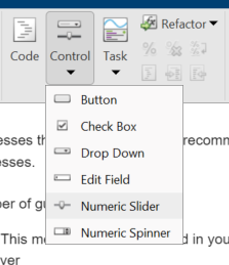

To edit the slider configurations, right click on the slider and select "Configure Control". We want to set the min to 6, the max to 20, the step to 1, and the Run to Nothing. You can set the label and default value to be whatever you like.

  **Try**. Use the same row and column variables from above and transform them into the Numeric Slider live control. Configure the controls as stated above. 

% Write your code here
rows = 15;
columns = 15;

### Making something new from something old

You can use old variables to make new ones. We want to create two new variables that are equal to 1 less than the row and column variables. These variables will be the actual boundaries of our treasure map.

  **Try**. Create two new variables called *limitC* and *limitR* that subtract one from the *columns* and *rows* variables, respectively.

% Write your code here
limitC = columns - 1;
limitR = rows - 1;

### Using your first built-in function

A built-in MATLAB function allows you to easily execute any kind of operation or task, such as generating new variables. The `randi` function will generate a pseudorandom integer between 1 and the number we specify. For example, if we want to generate a random integer between 1 and 10, we can run the following command. Notice that if you run it multiple times, you will see a different result each time.

randi(10)

ans = 7

Here is the documentation page where you can find more information about the `randi` function:

[Uniformly distributed pseudorandom integers - MATLAB randi (mathworks.com)](https://www.mathworks.com/help/matlab/ref/randi.html)

For the purposes of our game, we want to specify the maximum value to be the boundaries of our treasure map which we defined above. This will allow us to obtain random coordinates for our treasure chest.

  **Try**. Use the `randi` function to create two new variables corresponding to an X and Y location for the treasure, called *treasureX* and *treasureY*.

% Write your code here
treasureX = randi(limitC);
treasureY = randi(limitR);

## Section 2: Working with Matrices

MATLAB was originally created to help solve complex linear algebra problems involving matrices. A matrix is an r-by-c array of numbers, where r is the number of rows and c is the number of columns. We already specified our row and column lengths earlier, so now we can use those variables to create the matrix representing our entire treasure map.

### It's all full of zeros

To create our first matrix, we want to use a built-in MATLAB function called `zeros`. This function creates a matrix of zeros whose size is the determined by the two inputs you specify. In our case, we want the size to be equal to the *rows* and *columns* variables we made earlier. More information on the `zeros` function can be found here: 

[Create array of all zeros - MATLAB zeros (mathworks.com)](https://www.mathworks.com/help/matlab/ref/zeros.html#:~:text=X%20%3D%20zeros(%20sz%20)%20returns,2%2Dby%2D3%20matrix.&text=X%20%3D%20zeros(___%2C%20typename%20)%20returns%20an%20array%20of,%2C%208%2Dbit%20integer%200%20.)

  **Try**. Using the `zeros` function, create a new variable to represent our blank treasure map. Put in any size you'd like, run the code, and see the results. When you are done, set the size to be *rows* and *columns* - your output should be a matrix of zeros with dimensions equal to your *rows* and *columns *variables.

% Write your code here
map = zeros(rows, columns);

### Add some pcolor

Now that we have our map, let's use the `pcolor` function to visualize it. The `pcolor` function will display our matrix data as an array of colored cells. More information on the `pcolor` function can be found here: 

[Pseudocolor plot - MATLAB pcolor (mathworks.com)](https://www.mathworks.com/help/matlab/ref/pcolor.html)

  **Try**. Call the `pcolor` function on our map variable. If you called the function correctly, it should look like this: 

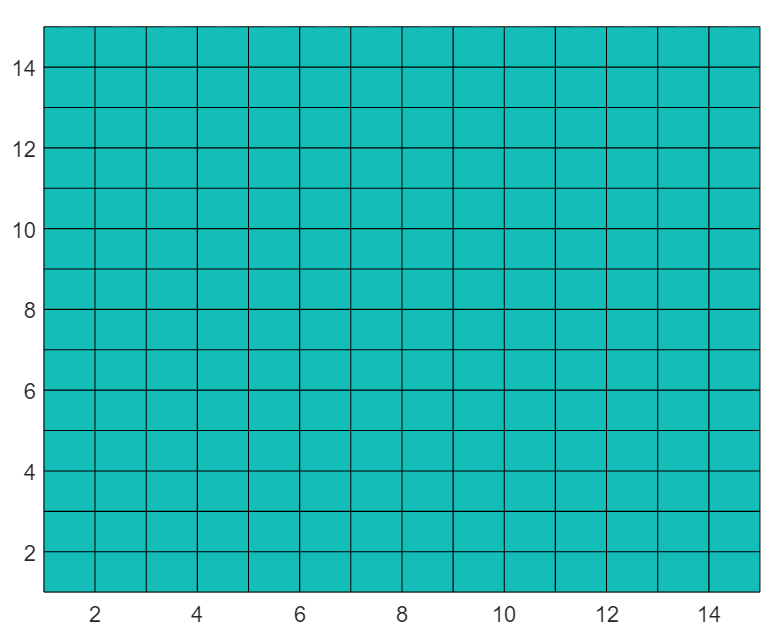

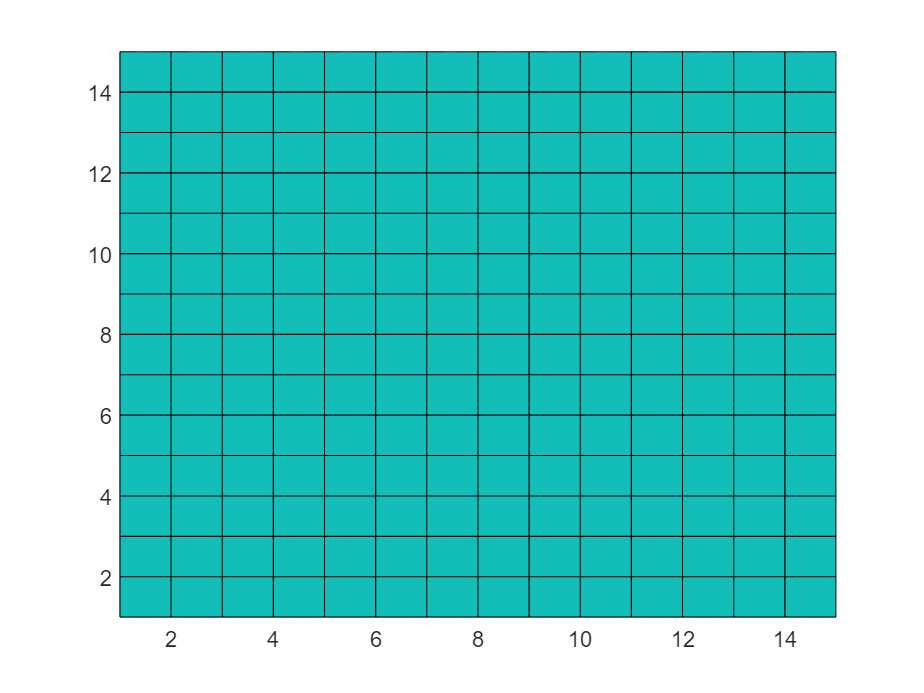

% Write your code here
pcolor(map);

### Not a number

Great! Now we have a map that is the correct size, but we want our blank map to be white instead of the teal color we saw above. To accomplish this, we'll need to learn about something called NaN.

NaN stands for Not a Number. In MATLAB, NaN is used to represent values that are not real or complex numbers; for example, the expression 0/0 will result in NaN. If you want to learn more about NaN, check out this external link:

[NaN - Wikipedia](https://en.wikipedia.org/wiki/NaN)

MATLAB interprets NaN values as white, and this is exactly what we want for our empty map, so we need MATLAB to go through our entire matrix of zeros and change each value to NaN. There is a neat trick we can use to do this called *logical indexing*, which you can see in the code below:

** Demonstration**. Run the below code and see how it changes the *map* matrix. 

map(map == 0) = NaN

map =    NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


This line of code is essentially saying "Find every value in *map* that is equal to 0, and set it equal to NaN". If you want to learn more about logical indexing, you can read more about it here, under the section titled "Logical Indexing":

[Logical Indexing - MATLAB](https://www.mathworks.com/company/newsletters/articles/matrix-indexing-in-matlab.html#:~:text=In%20logical%20indexing%2C%20you%20use,that%20are%20greater%20than%2012.)

Now let's try calling `pcolor` again and check that the map appears white.

  **Try**. Call the `pcolor` function on our updated map variable. It should now look like this: 

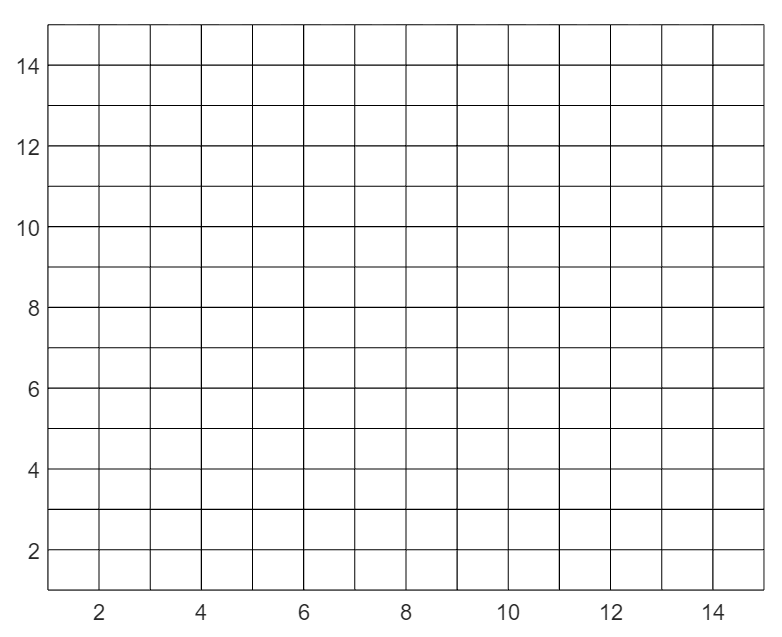

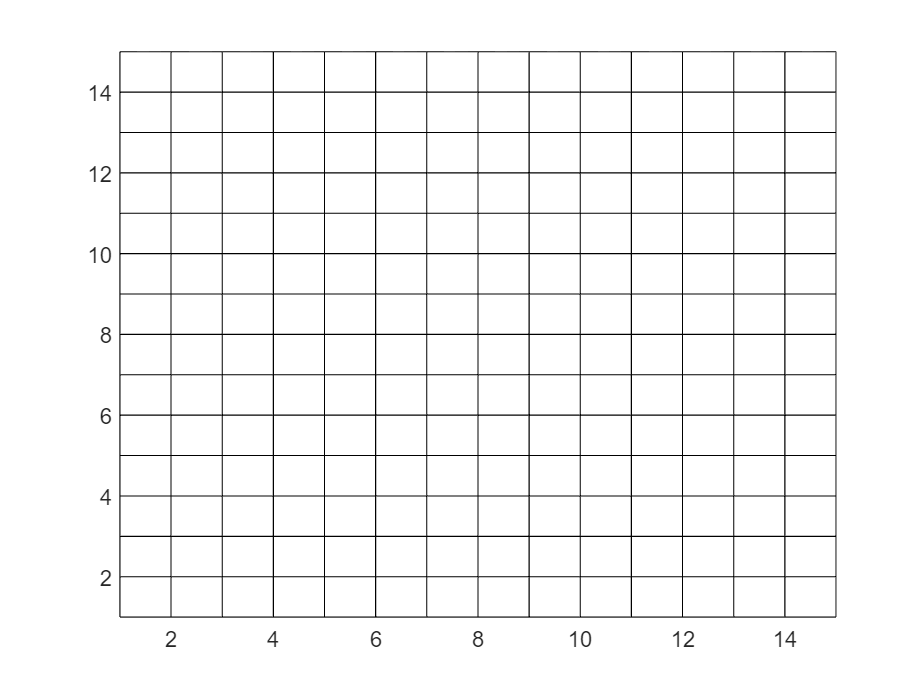

% Write your code here
pcolor(map);

### The coordinates

Now we want to map each of the points in our matrix to an X,Y coordinate so that we can store and plot the player's guesses. To do this, let's define two vectors: one which contains every possible X coordinate, and another which contains every possible Y coordinate.

  **Try**. Define two new variables, called *xCoords* and *yCoords*, which contain all possible values of X and Y on our map.

% Write your code here
xCoords = 1:columns;
yCoords = 1:rows;

### Taxicab metric

Now that we have our treasure map and location, we want to calculate the distance from each coordinate point to our treasure. We can use the Taxicab Metric, also called Manhattan distance, to calculate the distance between two coordinate points. This external link provides some great insight into the Taxicab Metric: 

[Taxicab geometry - Wikipedia](https://en.wikipedia.org/wiki/Taxicab_geometry)

The Taxicab Metric requires us to find the absolute value. There is a built-in MATLAB function called `abs` that can do this for us. More information on the` abs` function can be found here: 

[Absolute value and complex magnitude - MATLAB abs (mathworks.com)](https://www.mathworks.com/help/matlab/ref/abs.html)

  **Try**. Equate this value: `abs(treasureY - xCoords) + abs(treasureX - yCoords)'`  to a variable called *taxiMatrix.*

% Write your code here
taxiMatrix = abs(treasureY - xCoords) + abs(treasureX - yCoords)'

taxiMatrix =     17    16    15    14    13    12    11    10     9     8     7     6     5     4     5
    16    15    14    13    12    11    10     9     8     7     6     5     4     3     4
    15    14    13    12    11    10     9     8     7     6     5     4     3     2     3
    14    13    12    11    10     9     8     7     6     5     4     3     2     1     2
    13    12    11    10     9     8     7     6     5     4     3     2     1     0     1
    14    13    12    11    10     9     8     7     6     5     4     3     2     1     2
    15    14    13    12    11    10     9     8     7     6     5     4     3     2     3
    16    15    14    13    12    11    10     9     8     7     6     5     4     3     4
    17    16    15    14    13    12    11    10     9     8     7     6     5     4     5
    18    17    16    15    14    13    12    11    10     9     8     7     6     5     6


In this matrix, the 0 is the location of the treasure, and every other value represents the distance between that coordinate and the treasure. This distance is calculated by finding how far the coordinate is from the treasure in the x-direction, and then adding how far the coordinate is from the treasure in the y-direction.

### Change the treasure

Now that we have our matrix filled in, we want to make sure the treasure shows up correctly when we plot it later. You can index into your matrix and change specific values. We want to index to our treasure's location and change it to a high value. I recommend 500. 

% Set treasure to very high value so it appears correctly
finalMap(treasureY,treasureX) = 500

finalMap =     17    16    15    14    13    12    13    14    15    16    17    18    19    20    21
    16    15    14    13    12    11    12    13    14    15    16    17    18    19    20
    15    14    13    12    11    10    11    12    13    14    15    16    17    18    19
    14    13    12    11    10     9    10    11    12    13    14    15    16    17    18
    13    12    11    10     9     8     9    10    11    12    13    14    15    16    17
    12    11    10     9     8     7     8     9    10    11    12    13    14    15    16
    11    10     9     8     7     6     7     8     9    10    11    12    13    14    15
    10     9     8     7     6     5     6     7     8     9    10    11    12    13    14
     9     8     7     6     5     4     5     6     7     8     9    10    11    12    13
     8     7     6     5     4     3     4     5     6     7     8     9    10    11    12


### Saving colors

The last thing we want to do before setting up our plot is set the colors for our colormap. A colormap is a matrix containing values which represent how far away you are from the treasure. I chose nine different colors for my colormap. The last color should represent the treasure.

One of the ways that colors are represented in MATLAB is by their RGB value. RGB stands for Red, Green, Blue. All possible colors can be created depending on how much red, green, and blue you put into them.

An option to find the RGB values for the colors you want to use is to use a built-in MATLAB app called uisetcolor. You can type this into the MATLAB Command Window, and the app will pop up and let you pick colors. It will then output the RGB value for you to use. More information on uisetcolor can be found here:

[Open color picker - MATLAB uisetcolor (mathworks.com)](https://www.mathworks.com/help/matlab/ref/uisetcolor.html)

%The colormap for the board with different colors to simulate an island
cmap = [0.6706 0.4588 0.0392; 0.4667 0.6745 0.1882; 0 1 0;1 0.9059 0.5216;0.0588 1 1; 0 0 1; 0 0.4471 0.7412;0.0314 0 0.4706; 1 1 0]

cmap =     0.6706    0.4588    0.0392
    0.4667    0.6745    0.1882
         0    1.0000         0
    1.0000    0.9059    0.5216
    0.0588    1.0000    1.0000
         0         0    1.0000
         0    0.4471    0.7412
    0.0314         0    0.4706
    1.0000    1.0000         0


## Section 3: Creating Plots and Modifying Them

By now, I'm sure you are sick of just looking at numbers and matrices and want to start plotting to make something pretty. 

### Add some pcolor

Now that we have our Taxicab matrix set up, we want to display all the values to start creating our treasure map. Let's use the `pcolor `function to create a pseudocolor plot of our matrix. A pseudocolor plot displays matrix data as an array of colored cells. More information on the pcolor function can be found here: 

[Pseudocolor plot - MATLAB pcolor (mathworks.com)](https://www.mathworks.com/help/matlab/ref/pcolor.html)

Let's try running the `pcolor` function on our finalMap variable first. If you called the function correctly, it should look similar to the picture below. The yellow represents the treasure location. Try running the function multiple times and see what happens to the treasure location. 

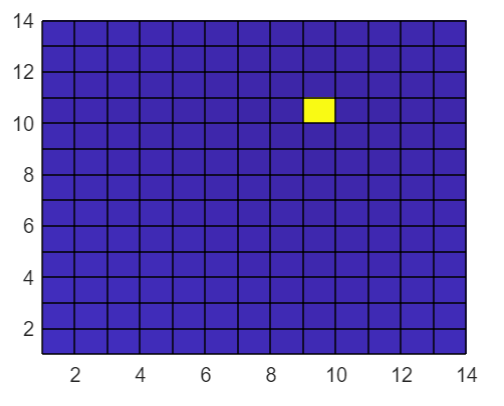

%try calling the pcolor function on the finalMap variable
pcolor(map)

Placeholder for later. Skip this section for now.

hold on

### Colormap it up

Remember the colormap values that we picked earlier. Let's use those colors so that our treasure is no longer stranded in the middle of the ocean. If we use the `colormap` function and input our colormap values from before, we should get something like the picture below:

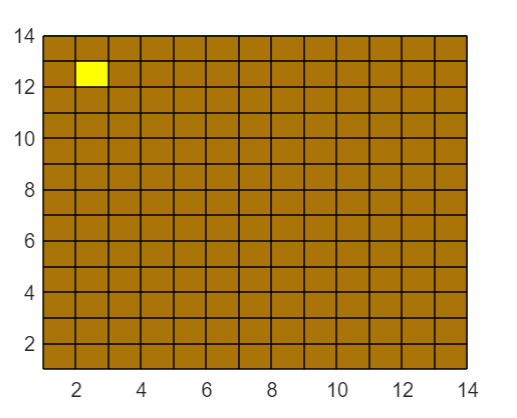

The treasure should now be equal to the last value in your colormap (mine is yellow), and everything else should be equal to the first value in your colormap (mine is brown). More information on the colormap can be found here:

[View and set current colormap - MATLAB colormap (mathworks.com)](https://www.mathworks.com/help/matlab/ref/colormap.html)

colormap(cmap)

### Colorbars to see our color

I bet you are wondering where all the other colors in our colormap are. Let's include a colorbar to make it easier to see those colors and how they correspond to values on our plot. Let's also set the colorbar equal to a variable so we can add to it later. More information on colorbars can be found here:

[Colorbar showing color scale - MATLAB colorbar (mathworks.com)](https://www.mathworks.com/help/matlab/ref/colorbar.html)

 c = colorbar

c =   ColorBar with properties:

    Location: 'eastoutside'
      Limits: [0 1]
    FontSize: 9
    Position: [0.8310 0.1095 0.0381 0.8159]
       Units: 'normalized'

  Show all properties


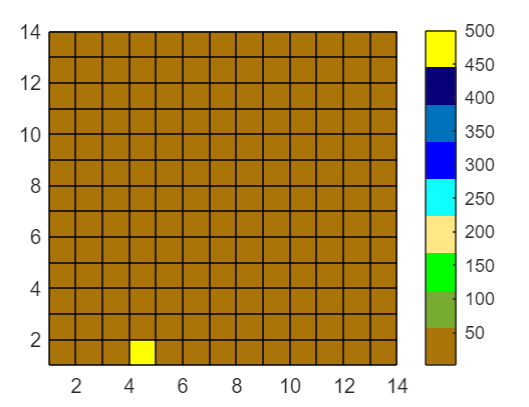

### Changing limits

If we look at the colorbar that MATLAB created, it tells us that the upper limit is 500 and the lower limit is 0. Remember, our Taxicab matrix contains all the distances from the treasure. Since my map is 14 x 14, the furthest point from the treasure will be around 20. 20 is less than 50, so all the values that are not the treasure become brown in our plot. 

In order to change this, we need to use the` clim `function to change our colormap limits. 

Try changing the upper limit value and see what happens. Try changing the lower limit value and see what happens. For the best results, I recommend setting the upper limit to rows*2 and the lower limit to 0. Your plot should look something like the below image if you set the same limits as I did:

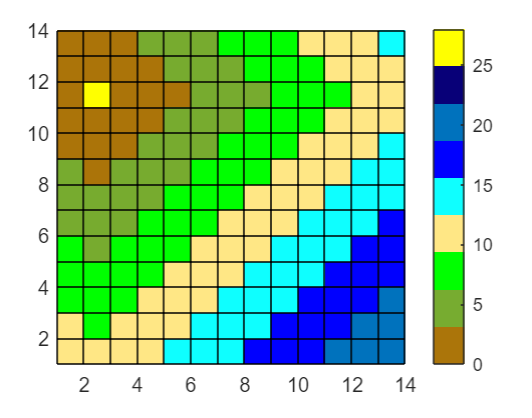

More information on the `clim` function can be found here:

[Set colormap limits (Renamed from caxis in R2022a) - MATLAB clim (mathworks.com)](https://www.mathworks.com/help/matlab/ref/clim.html)

clim([0 rows*2])

### Labeling the color

It will make it easier for players to interpret our colorbar if we add labels to it. To do this, we need to use the colorbar variable we made earlier and access the TickLabels property from it. We can do this with the following statement: var.TickLabels. These were the values I used for my TickLabels: {'Dirt', 'Woods', 'Grass', 'Sand', 'Shore', 'Shallow', 'Deep', 'Ocean', 'Treasure'}. You are welcome to change them if you like; just make sure the number of labels is equal to the number of colors you chose. Your colorbar should now look like this: 

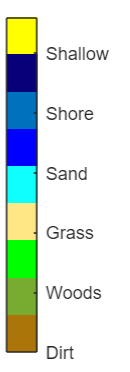

c.TickLabels = {'Dirt','Woods','Grass','Sand','Shore','Shallow','Deep','Ocean', 'Treasure'}

c =   ColorBar with properties:

    Location: 'eastoutside'
      Limits: [0 28]
    FontSize: 9
    Position: [0.8310 0.1095 0.0381 0.8159]
       Units: 'normalized'

  Show all properties


### Fix the space

You may have noticed that the Tick Labels in our colorbar do not align correctly. Fortunately, the colorbar variable has a property called Ticks that can fix this. It can be accessed in the following way: var.Ticks.

We set the Ticks property equal to three numbers. The first number is the min, the second number is the tick spacing, and the third number is the max.

Try changing the three values one at a time and see what happens to the ticks in your colorbar. I have provided some min, max, and spacing values that worked for me. The division by 9 is based on the nine colors I chose for the colormap. If you chose more or less, make sure to change the number accordingly. 

min = 1;
spacing = rows*2/9;
max = rows*2;

c.Ticks = min:spacing:max

c =   ColorBar with properties:

    Location: 'eastoutside'
      Limits: [0 28]
    FontSize: 9
    Position: [0.8310 0.1095 0.0381 0.8159]
       Units: 'normalized'

  Show all properties


### Ticks tock

Now that we have our colorbar set up, let's make our x and y axes look better. Similar to how we set the ticks for the colorbar, we can also set ticks for the x and y axes. There are functions called `xticks` and` yticks` that will let us do this quickly. For the input of the function, we give it three numbers spaced with a colon. The three numbers are the min, the spacing, and the max. More information on these functions can be found here:

[Set or query x-axis tick values - MATLAB xticks (mathworks.com)](https://www.mathworks.com/help/matlab/ref/xticks.html)

Try playing around with these numbers. When you are done, I recommend setting the min to 1, the spacing to 1, and the max to the limitC or limitR value that we made above. Your plot should look like this when done:

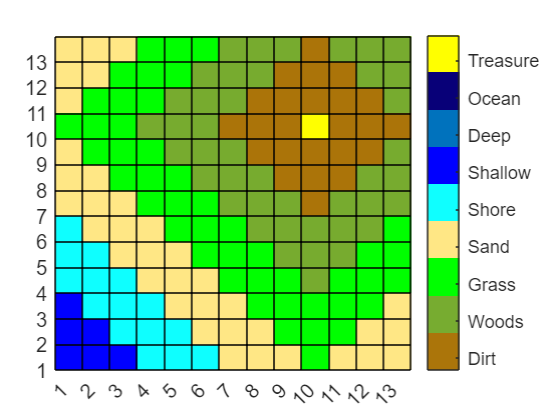

xticks(1:1:limitC)
yticks(1:1:limitR)

### Title time

We should add a title to help instruct the player on what they should do. MATLAB has another built-in function to do just that called `title`. Just call the `title` function, and the input will take a string of what you want it to say. I chose to say, "Find the Treasure!". More info on the` title` function can be found here:

[Add title - MATLAB title (mathworks.com)](https://www.mathworks.com/help/matlab/ref/title.html)

The title should look like this:

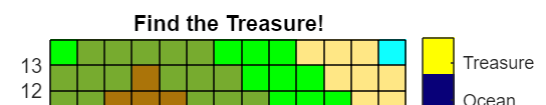

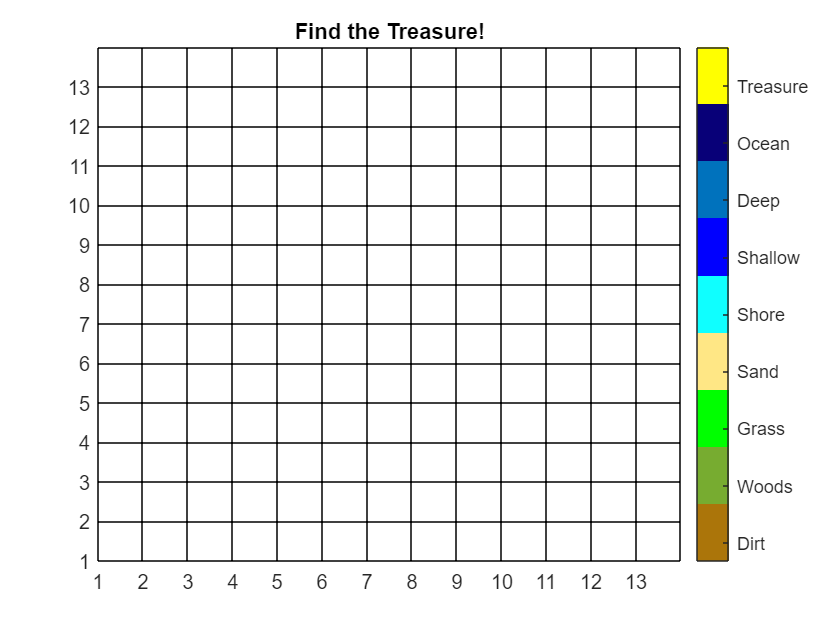

title("Find the Treasure!")

### Go back up and fix it

Before we move on to the next section, we need to go back to line 23 and change the input of the `pcolor` function to our NaN matrix. This will fill our plot with white squares. We were using the Taxicab matrix for learning purposes. Now we want to set it up so someone can play the game and guess where the treasure is. Calling pcolor with the NaN matrix will look like this:

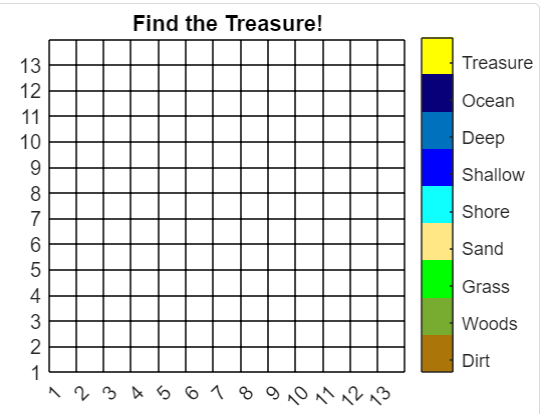

## Section 4: User Input and If Statements 

When making a game, you will need to gather some input from the user. This could include mouse clicks, button presses, or keyboard strokes. In the case of our treasure hunt game, we want to take in two numbers representing the player's x and y coordinate guess. 

### Guess what

Let's make two new variables for the player's guess. I called mine guessX and guessY.

guessX = 1

guessX = 1

guessY = 1

guessY = 1

### Live guessing

It will get annoying for the user to delete and type in a new guess every time, and we want to make sure they are guessing within the bounds of our plot. Let's use another live control called Numeric Spinner to avoid these issues. We want to right click on it and select Configure Control. There, we can set the label, set the min to 1, set the max to limitC or limitR, and set Run to Nothing. 

guessX = 10

guessX = 10

guessY = 9

guessY = 9

### Put in one guess

Now that we have the user's guess, we need to show where their guess is by updating it on our plot. To do this, we must index into our NaN matrix and change the guess value to the value in our Taxicab matrix. Then we need to call pcolor again on our NaN matrix to update it. I tried the guesses X:6 and Y:4, and it looks like this:

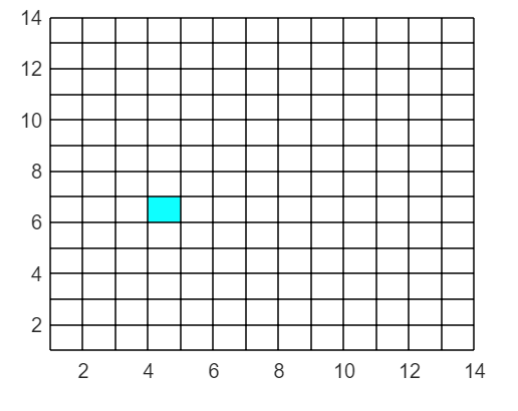

%map(guessX,guessY) = finalMap(guessX,guessY);
%pcolor(map)

### Fix our guess

Now, if you look at the picture above, you will see that my guess is at (4,6) and not (6,4) like I intended. This is because MATLAB matrix indexing works the opposite way of traditional X,Y grid indexing. Therefore to show the correct guess, we need to switch the X and Y guesses for both matrices. Once we swap X and Y, the plot will look like this:

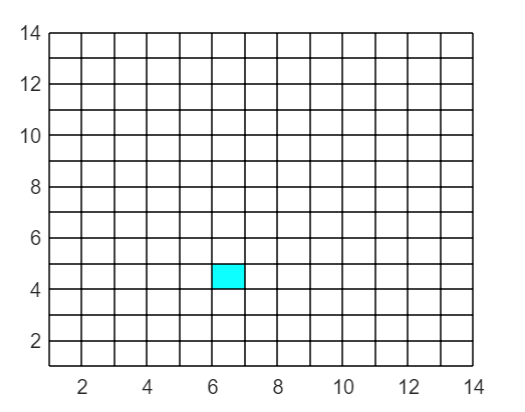

More information on matrix indexing can be found here:

[Matrix Indexing in MATLAB - MATLAB & Simulink (mathworks.com)](https://www.mathworks.com/company/newsletters/articles/matrix-indexing-in-matlab.html)

% map(guessY,guessX) = finalMap(guessY,guessX);
% pcolor(map)

### Hold on

You may have noticed that all the beautiful things we added above, like the colorbar, title, and extra ticks, are all gone. That is because we created an entirely new plot. If we want our changes to remain on the same plot, we need to go back to line 24 and type "hold on". This will retain all the changes we added previously. More info about "hold on" can be found here:

[Retain current plot when adding new plots - MATLAB hold (mathworks.com)](https://www.mathworks.com/help/matlab/ref/hold.html)

Your new plot should look like this:

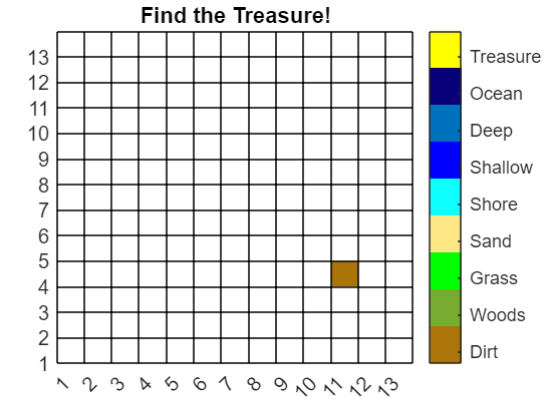

If you go back to lines 39 and 40 where we added our live control, you can change your guess and select Run Section instead of the Run button to see many new squares become filled in, like so:

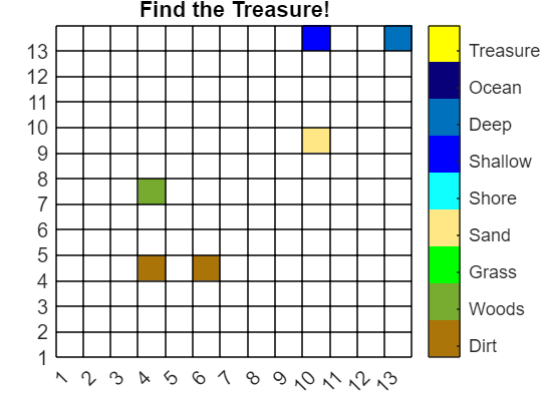

There are a few other things we need to take care of before our game is completely functional. If you click the Run button, you will see that it will automatically put in the guess that is already there. This can be frustrating for the player. To prevent this, let's add an if statement. An if statement is a statement that will only execute the code inside it if the statement is true. 

You can learn how to use if statements here: 

[Execute statements if condition is true - MATLAB if elseif else (mathworks.com)](https://www.mathworks.com/help/matlab/ref/if.html)

Now, create your own if and else statement. Create a new variable called testNum that equals any number. If testNum is greater than 10, testNum should equal "Too Big". Otherwise, set testNum equal to "Perfect".

  **Try**.  Change the value of testNum and see how its value changes. 

testNum = 0

testNum = 0


if (testNum > 10)
    testNum = "Too Big"
else
    testNum = "Perfect"
end

testNum = "Perfect"

### If and else

Back to our game, let's use our guessNum variable from earlier to see if the player has made a guess already. For the if statement's expression, we want to check if the guessNum is greater than zero. If the guessNum is zero, that means we have started the game. Let's put the guessX and guessY live control inside the if statement. We also want to update the NaN matrix and call pcolor again to update the player's guess.

  **Try**. Run this section to see if there is any output.

  **Pro-tip**. Include your expression inside parentheses to make it easier to read.

if(guessNum > 0)
    guessX = 5;
    guessY = 3;
    %Upadate the NaN matrix
    map(guessY,guessX) = finalMap(guessY,guessX);
    %Show the Update
    pcolor(map)
end

 **Reflect**. If you tried running the section above, you should have noticed that it does not produce any output. This is because the value of guessNum is always zero. Therefore, MATLAB will not execute the code inside the if statement because its expression is not true. In its current state, the value of guessNum never changes, so let's add an else statement and increment the value of guessNum inside it so the game can start. 

  **Try**. Add an else statement to increment the value of guessNum by one.

  **Pro-tip**. The else statement shares the end statement with the if statement.

if(guessNum > 0)
    guessX = 11;
    guessY = 3;
    %Upadate the NaN matrix
    map(guessY,guessX) = finalMap(guessY,guessX);
    %Show the Update
    pcolor(map)
else
    guessNum = guessNum + 1;
end

Now the guessNum will only increment if the player has not started the game. But we also want it to increase for every guess the player makes.

  **Try**. Increment guessNum inside the if statement so we can keep track of how many guesses the player has made.

if(guessNum > 0)
    guessX = 11;
    guessY = 3;
    %Upadate the NaN matrix
    map(guessY,guessX) = finalMap(guessY,guessX);
    %Show the Update
    pcolor(map)

    guessNum = guessNum + 1;
else
    guessNum = guessNum + 1;
end

### Check for the treasure

Our game is almost completely playable. Now we need to check if the player found the treasure to end the game. To do this, we must add an if and an else statement inside our previous if statement. Inside the new if statement, we want to call pcolor on our Taxicab matrix to fill in the entire treasure map. And we want to call the `title` function again to display "Treasure Found!". You can also include guessNum inside the `title` function to display the number of guesses the player made.

  **Try**. Add an if and else statement into our current if statement. The expression for the if statement should check if guessX is equal to treasureX and if guessY is equal to treasureY. If this is true, we want to fill in the whole plot with the Taxicab matrix and change the title to "Treasure found!" with the number of guesses.

  **Pro-tip**. Use a double ampersand (&&) to combine two expressions into one if statement. 

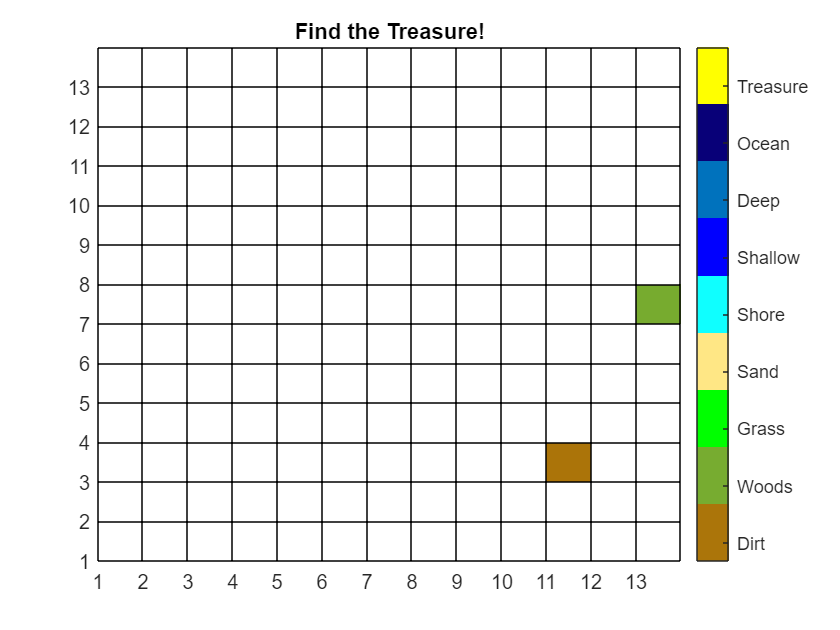

if(guessNum > 0)
    guessX = 13;
    guessY = 7;
    %If the guess is equal to the treasure
    if(guessX == treasureX)&&(guessY == treasureY)
        %Fill in the whole grid
        pcolor(finalMap);
        %Display the new title
        finish = "Treasure Found! Guesses: " + guessNum;
        title(finish);
    
    %If the guess is not equal to the treasure
    else
        %Upadate the NaN matrix
        map(guessY,guessX) = finalMap(guessY,guessX);
        %Show the Update
        pcolor(map)
        
    end

    guessNum = guessNum + 1;
else
    guessNum = guessNum + 1;
end

I have provided a finalized version of the above code section. Feel free to use this after you finish the Creating and Using Functions section. 

Finalized player interaction section:

% Play Game
%  
% 
% if(guessNum < 0)
%     guessX = 5;
%     guessY = 1;
% 
%     Run function to check guesses
%     playGame(treasureX,treasureY,map,finalMap,guessX,guessY,guessNum)
%     guessNum = guessNum + 1;
% else
%     Increments the Guess Numbers to start the game
%     guessNum = guessNum + 1;
% end

## Section 5: Creating and Using Functions

We have used many built-in MATLAB functions to build this game, but did you know that you can also create your own? It is important to make your own function when you have code that will be executed multiple times with different inputs. 

More information on declaring your own functions can be found here:

[Declare function name, inputs, and outputs - MATLAB function (mathworks.com)](https://www.mathworks.com/help/matlab/ref/function.html)

  **Try**.Try creating your own function that adds 5 to an inputted number and returns that value. 

  **Pro-tip**.Notice that we must call the function before its declaration.

addFive(3);

function fiveMore = addFive(num)
    fiveMore = num + 5;
end

### Function junction

Now that we know a bit about functions, let's use one to make our code easier to read.

  **Try**. Create your own function to replace the if and else statement inside the if statement that we made earlier.

## Further Exploration

I have provided a function that we can use to run our game a bit more smoothly. Look over the function and find what code above can be replaced with this one function call.

Finalized Function:

function playGame(tX,tY,m,fm,gX,gY,gN)
    
    %If the guess is equal to the treasure location
    if(gX == tX)&&(gY == tY)
        %Fill in the whole grid
        pcolor(fm);
        %Display the new title
        finish = "Treasure Found! Guesses: " + gN;
        title(finish);
    %If the guess is not equal to the treasure
    else
        %Fill in the color of the location that was guessed
        m(gY,gX) = fm(gY,gX);
        pcolor(m);
        
        %Display hint and guess number
        help = "You are " + string(fm(gY,gX)) + " away from the treasure.";
        guess = "Guess: " + gN;
        disp(help);
        disp(guess);
        disp("Guess again!");
        
    end
end